# Caculate the opimal intersection sequence between CAVs and pedestrians

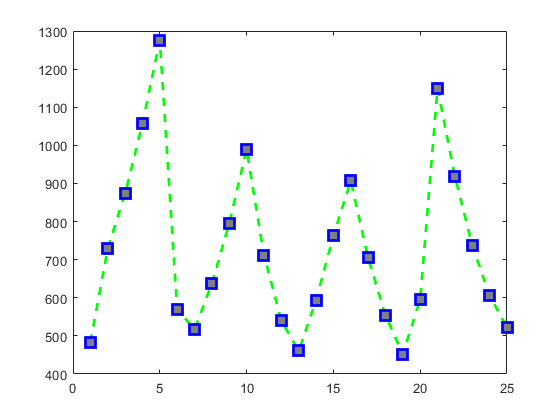

%This is a example of two lanes and 8 CAVs
%definitions of CAVs pedestrians
%d_vi_exit = [30 55 100];
%d_vj_exit = [30 80 124];
d_vi_exit = [40 65 90 115];
d_vj_exit = [30 60 90 120];

d_base = 24;
w_p = 6; %weighting factor of pedestrians
w_v = 1; %weighting factor of CAV

LOSS_rec = 10000;
i_rec = 0;
j_rec = 0;
% pedestrian cross before car_i, car_j
m = length(d_vi_exit);
n = length(d_vj_exit);
result = zeros([(m+1) (n+1)]);
for i = 0 : m
    for j = 0 : n
        if i == 0
            t_vi_exit = 0;
        else
            t_vi_exit = d_vi_exit(i)/10; 
        end
        if j == 0
            t_vj_exit = 0;
        else
            t_vj_exit = d_vj_exit(j)/10;
        end
        
        t_v_exit = max(t_vi_exit , t_vj_exit);
        t_p_wait = t_v_exit +1.2;                 % pedestrian waiting time
        p_loss = t_p_wait;
        
        if i==m
            d_loss_a = 0;
        else
            d_loss_a = (m-i)*( -(d_vi_exit(i+1)-10) + 10*(t_p_wait+(4/1)+4.7/2)-(-10+18));% cause problem.
            d_k_sum = 0;
            if m-i-1 == 0
                d_k_sum = 0;
            else
                for k = 1:m-i-1       % m-i-1>0
                    d_k = d_vi_exit(i+1+k) - d_vi_exit(i+k);
                    d_k_sum = d_k_sum + d_k;   %跟随避让行人的CAV增加的距离
                end
            end
            d_loss_a = d_loss_a + (m-i-1)*d_base - d_k_sum;
        end
        if j==n
            d_loss_b = 0;
        else
            d_loss_b = (n-j)*( -(d_vj_exit(j+1)-10) + 10*(t_p_wait+(8/1)+4.7/2) + (-8));
            d_k_sum = 0;   %计算跟随避让行人的CAV增加的距离
            if n-j-1 == 0
                d_k_sum = 0;
            else
                for k = 1:n-j-1       % m-i-1>0
                    d_k = d_vj_exit(j+1+k) - d_vj_exit(j+k);
                    d_k_sum = d_k_sum + d_k;   %跟随避让行人的CAV增加的距离
                end
            end
            d_loss_b = d_loss_b + (n-j-1)*d_base - d_k_sum;    %最终的d_loss_a计入CAV增加的跟随距离
        end
        w_p = 3;
       %LOSS = w_p*p_loss + w_v*d_loss_a + w_v*d_loss_b;  % sum of loss;
        LOSS = w_p * power(p_loss,2) + w_v*d_loss_a + w_v*d_loss_b;  % sum of loss;
        
        result(i+1, j+1) = LOSS;
        if LOSS < LOSS_rec            
            LOSS_rec = LOSS;            
            i_rec = i;    
            j_rec = j;            
        end
    end
end

x = 1:(m+1)*(n+1);
y = result(:);
 plot(x,y,'--gs',...
     'LineWidth',2,...
     'MarkerSize',10,...
     'MarkerEdgeColor','b',...
     'MarkerFaceColor',[0.5,0.5,0.5]);


outLoss = y;
outOrder = [i_rec j_rec];